clear;
syms A B C D q1 q2 q3 q4 alpha q real
DH = [pi/2 B A q1; 0 C 0 q2; pi/2 D 0 q3; 0 0 q4 0];

In the function directkin, we simply extract from DH for ith row a homogeneus matrix representing the orientation of RFi wrt RFi-1, obtaining thus in this case 4 homogeneus matrices (obtained by multiplying the matrix for rotation and translation along the joint axis zi-1 and the matrix for rotation and translation along xi). 

Just to illustrate for the first joint, butevery homogeneus matrix will be obtained in this way

hom = hom_mat(rot_mat("z",q),[0,0,A]) * hom_mat(rot_mat("x",alpha),[B,0,0])

$$hom = \left(\begin{array}{cccc} \cos\left(q\right) & -\cos\left(\alpha \right)\,\sin\left(q\right) & \sin\left(\alpha \right)\,\sin\left(q\right) & B\,\cos\left(q\right)\\ \sin\left(q\right) & \cos\left(\alpha \right)\,\cos\left(q\right) & -\cos\left(q\right)\,\sin\left(\alpha \right) & B\,\sin\left(q\right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & A\\ 0 & 0 & 0 & 1 \end{array}\right)$$

[T,A] = directkin(DH);
p = simplify(T(1:3,4))

$$p = \begin{array}{l} \left(\begin{array}{c} \cos\left(q_{1}\right)\,\sigma_{1}+q_{4}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\,\sigma_{1}+q_{4}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ A+\text{D}\,\sin\left(q_{2}+q_{3}\right)-q_{4}\,\cos\left(q_{2}+q_{3}\right)+C\,\sin\left(q_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=B+\text{D}\,\cos\left(q_{2}+q_{3}\right)+C\,\cos\left(q_{2}\right) \end{array}$$

J = simplify(A{1}(1:3,1:3)' * jacobian(p,[q1,q2,q3,q4]))

$$J = \begin{array}{l} \left(\begin{array}{cccc} 0 & q_{4}\,\cos\left(q_{2}+q_{3}\right)-\text{D}\,\sin\left(q_{2}+q_{3}\right)-C\,\sin\left(q_{2}\right) & q_{4}\,\cos\left(q_{2}+q_{3}\right)-\text{D}\,\sin\left(q_{2}+q_{3}\right) & \sin\left(q_{2}+q_{3}\right)\\ 0 & \sigma_{1}+C\,\cos\left(q_{2}\right)+\sigma_{2} & \sigma_{1}+\sigma_{2} & -\cos\left(q_{2}+q_{3}\right)\\ -B-\sigma_{1}-C\,\cos\left(q_{2}\right)-\sigma_{2} & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\text{D}\,\cos\left(q_{2}+q_{3}\right)\\ \sigma_{2}=q_{4}\,\sin\left(q_{2}+q_{3}\right) \end{array}$$

J = subs(J,[B,D],[0 0])

$$J = \left(\begin{array}{cccc} 0 & q_{4}\,\cos\left(q_{2}+q_{3}\right)-C\,\sin\left(q_{2}\right) & q_{4}\,\cos\left(q_{2}+q_{3}\right) & \sin\left(q_{2}+q_{3}\right)\\ 0 & C\,\cos\left(q_{2}\right)+q_{4}\,\sin\left(q_{2}+q_{3}\right) & q_{4}\,\sin\left(q_{2}+q_{3}\right) & -\cos\left(q_{2}+q_{3}\right)\\ -C\,\cos\left(q_{2}\right)-q_{4}\,\sin\left(q_{2}+q_{3}\right) & 0 & 0 & 0 \end{array}\right)$$

simplify(det(J*J'))

$$ans = \begin{array}{l} \frac{C^{4}\,\cos\left(2\,q_{2}\right)}{4}-\frac{C^{4}\,\cos\left(2\,q_{3}\right)}{4}-\frac{C^{4}\,\sigma_{5}}{8}-\frac{C^{4}\,\sigma_{1}}{8}-{q_{4}}^{4}\,\sigma_{1}+\frac{C^{4}}{4}+{q_{4}}^{4}+\frac{9\,C^{2}\,{q_{4}}^{2}}{4}+\frac{C^{2}\,{q_{4}}^{4}}{4}+\frac{C^{4}\,{q_{4}}^{2}}{4}+\frac{17\,C^{2}\,{q_{4}}^{2}\,\cos\left(2\,q_{2}\right)}{8}-\frac{5\,C^{2}\,{q_{4}}^{2}\,\cos\left(2\,q_{3}\right)}{4}-\frac{C^{2}\,{q_{4}}^{4}\,\cos\left(2\,q_{2}\right)}{8}+\frac{C^{4}\,{q_{4}}^{2}\,\cos\left(2\,q_{2}\right)}{4}+\frac{C^{2}\,{q_{4}}^{4}\,\cos\left(2\,q_{3}\right)}{4}+\frac{C^{4}\,{q_{4}}^{2}\,\cos\left(2\,q_{3}\right)}{4}+\frac{C^{3}\,{q_{4}}^{3}\,\sin\left(3\,q_{3}\right)}{4}-\frac{5\,C^{2}\,{q_{4}}^{2}\,\sigma_{1}}{4}+\frac{C^{2}\,{q_{4}}^{2}\,\sigma_{4}}{8}-\frac{C^{2}\,{q_{4}}^{4}\,\sigma_{1}}{4}+\frac{C^{4}\,{q_{4}}^{2}\,\sigma_{5}}{8}+\frac{C^{4}\,{q_{4}}^{2}\,\sigma_{1}}{8}-\frac{C^{2}\,{q_{4}}^{4}\,\sigma_{4}}{8}+\frac{C^{3}\,{q_{4}}^{3}\,\sigma_{6}}{4}+\frac{C^{3}\,{q_{4}}^{3}\,\sigma_{2}}{4}+3\,C\,{q_{4}}^{3}\,\sin\left(q_{3}\right)+\frac{7\,C^{3}\,q_{4}\,\sin\left(q_{3}\right)}{4}+\frac{5\,C\,{q_{4}}^{3}\,\sigma_{3}}{2}+C^{3}\,q_{4}\,\sigma_{3}-\frac{C^{3}\,q_{4}\,\sin\left(3\,q_{3}\right)}{4}+\frac{C^{3}\,{q_{4}}^{3}\,\sin\left(q_{3}\right)}{4}-\frac{3\,C^{3}\,q_{4}\,\sigma_{6}}{4}-\frac{C\,{q_{4}}^{3}\,\sigma_{2}}{2}-\frac{C^{3}\,q_{4}\,\sigma_{2}}{4}+\frac{C^{3}\,{q_{4}}^{3}\,\sigma_{3}}{2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}=\sin\left(2\,q_{2}+3\,q_{3}\right)\\ \sigma_{3}=\sin\left(2\,q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(2\,q_{2}+4\,q_{3}\right)\\ \sigma_{5}=\cos\left(2\,q_{2}-2\,q_{3}\right)\\ \sigma_{6}=\sin\left(2\,q_{2}-q_{3}\right) \end{array}$$

Exercise 3

a = sqrt(2)/2; b = 1/2; c = sqrt(6)/4; d = sqrt(2)/4;
R1 = [0 -a a; 1 0 0; 0 a a];
R2 = [a b -b; 0 -a -a; -a b -b];
Rv = [c d -a; -c -d -a; -b sqrt(3)/2 0];

[alpha,beta,gamma] = euler_inv("zyx",R1)

alpha =     1.5708   -1.5708


beta =          0   -3.1416


gamma =     0.7854   -2.3562


alpha1 = alpha(1); beta1 = beta(1); gamma1 = gamma(1);
[alpha,beta,gamma] = euler_inv("zyx",R2)

alpha =          0   -3.1416


beta =     0.7854    2.3562


gamma =     2.3562   -0.7854


alpha2 = alpha(1); beta2 = beta(1); gamma2 = gamma(1);
[alpha,beta,gamma] = euler_inv("zyx",Rv)

alpha =    -0.7854    2.3562


beta =     0.5236    2.6180


gamma =     1.5708   -1.5708


av = alpha(1); bv = beta(1); cv = gamma(1);

Solution for the splines

syms v phi1 phi2 phi_v T1 T2 real
A = [2 3; 1 1];
b_a = [v*T1; phi_v-phi1];
b_b = [-v*(T2-T1); phi2-phi_v-v*(T2-T1)];
a = A \ b_a; b = A \ b_b

$$b = \left(\begin{array}{c} 3\,\varphi_{2}-3\,\varphi_{v}+2\,T_{1}\,v-2\,T_{2}\,v\\ 2\,\varphi_{v}-2\,\varphi_{2}-T_{1}\,v+T_{2}\,v \end{array}\right)$$

a2 = a(1); a3 = a(2); b2 = b(1); b3 = b(2);
eq = 1/T1^2 * (2*a2 + 6*a3) == ((1/(T2-T1))^2)*(2*b2)

$$eq = \frac{6\,\varphi_{1}-6\,\varphi_{v}+4\,T_{1}\,v}{{T_{1}}^{2}}=\frac{6\,\varphi_{2}-6\,\varphi_{v}+4\,T_{1}\,v-4\,T_{2}\,v}{{\left(T_{1}-T_{2}\right)}^{2}}$$

simplify(solve(eq,v))

$$ans = \frac{3\,{T_{1}}^{2}\,\varphi_{1}-3\,{T_{1}}^{2}\,\varphi_{2}+3\,{T_{2}}^{2}\,\varphi_{1}-3\,{T_{2}}^{2}\,\varphi_{v}-6\,T_{1}\,T_{2}\,\varphi_{1}+6\,T_{1}\,T_{2}\,\varphi_{v}}{2\,T_{1}\,T_{2}\,\left(T_{1}-T_{2}\right)}$$

T1 = 2.5; T2 = 3.5; phi1 = 1.57; phi_v = -0.78; phi2 = 0;
v = subs(solve(eq,v))

$$v = \frac{303}{700}$$

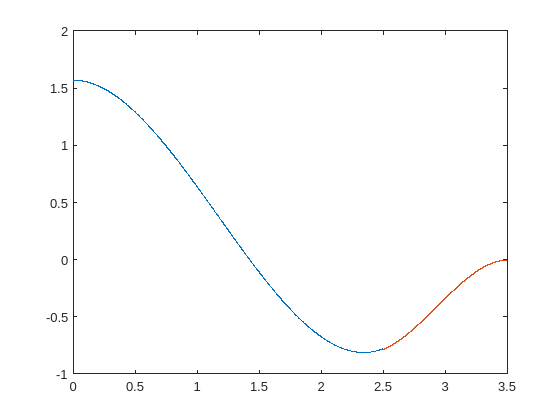

b3 = eval(subs(b3)); b2 = eval(subs(b2));
a3 = eval(subs(a3)); a2 = eval(subs(a2));

t = 0:0.001:1;
phiA = alpha1 + a2*t.^2 + a3*t.^3;
phiB = av + v*(T2-T1)*t + b2*t.^2 + b3*t.^3;
plot(t*T1,phiA); hold on; plot(t*(T2-T1)+T1,phiB)